# Matlab Project Assignment

# Task #04

## 1. Q1

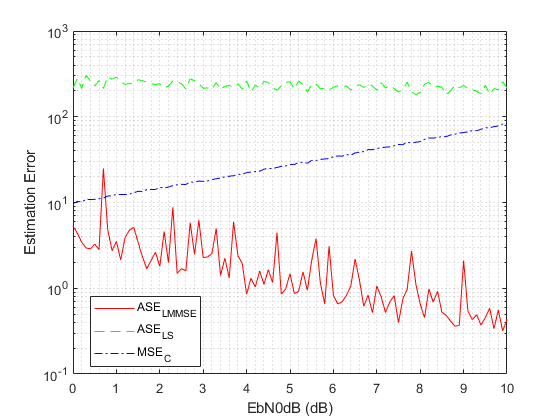

close all ; clear ; clc ;
rng(0) ; % reset the random number generator (for reproducibility)
% format long eng


MC = 1000;   % number of Monte Carlo runs for data
MC_channel = 1000; % number of Monte Carlo runs for channel
N_TX = 2; % number of TX antennas
N_RX = 2; % number of RX antennas

EbN0dB = 0:0.1:10;  % SNR vector in dB
NoSNRPoints = length(EbN0dB);   % length of SNR vector
EbN0 = 10.^(EbN0dB./10);  % SNR in linear scale
C = ( 1./EbN0 )./2 ;          % Find noise variance per I and Q component
sig = sqrt(C) ;        % Find noise standard deviation per I and Q component

A = sign(randn(N_TX,MC));  % random data for all runs, the same for all SNR points
C_A = 1*eye(N_RX, N_TX) ;  % Find data variance (variance of A)
% mean(A(:))
ASE_LS = zeros(NoSNRPoints,MC_channel);  % initialize the LS average square error (ASE)
ASE_LMMSE = zeros(NoSNRPoints,MC_channel);  % LMMSEE ASE
MSE_LMMSE = zeros(NoSNRPoints,MC_channel);  % theoretical MSE for LMMSE

for i = 1:NoSNRPoints        % generate noise realization for SNR values using
    for c = 1:MC_channel     % generate channel realization
        H= sqrt(1/2)*( randn(N_RX, N_TX) + 1j*randn(N_RX, N_TX) ) ; % generate complex channel response with total variance 1
        w= sig(i)*( randn(N_RX, 1) + 1j*randn(N_RX, 1) ) ; % generate complex noise with different sig for different SNR
        %         X = H*A(:,c) + w ;
        X = H*A + w ;

        C_W = (C(i)*eye(N_RX, N_TX)) ;
        LS = real( (inv(C_A)+H'*inv(C_W)*H)*H'*C_W*X  )  ; % Implement LS estimator and take only real part which contain the data
        LMMSE = real( inv(H'*H)*H'*X  )  ; % Implement LMMSE estimator and take only real part which contain the data
        ASE_LS(i,c) = mean((abs(LS-A)).^2,'all');  % Calculate average square error for LS
        ASE_LMMSE(i,c) = mean((abs(LMMSE-A)).^2,'all'); % Calculate average square error for LMMSE
        MSE(i,c) = sum(abs(diag(real( inv(C_A)+H'*inv(C_W)*H )))); % Implement theoritical MSE for LMMSE by taking real parts of diagonal elements
    end
end

MSE_C = mean(MSE,2) ; % Take average over different channel realization for MSE
ASE_LMMSE_C = mean(ASE_LMMSE,2) ; % Take average over different channel realization for ASE_LMMSE
ASE_LS_C = mean(ASE_LS,2) ; % Take average over different channel relaization for ASE_LS

fig1 = figure ;
semilogy(EbN0dB,ASE_LMMSE_C,'r-');
hold on
semilogy(EbN0dB,ASE_LS_C,'g--');
semilogy(EbN0dB,MSE_C,'b-.');
hold off
grid minor
xlabel('EbN0dB (dB)') ;
ylabel('Estimation Error') ;
legend('ASE_{LMMSE}','ASE_{LS}','MSE_{C}','Location','best') ;

exportgraphics(fig1,'THEplot.pdf')